# True Solution to Pozrikidis 2D Channel

## Calculating single point

L = 4; % length of permeable portion of the channel
H = 1; % radius of the channel
c = 2*H; % extension length of the channel
x =c/2;
y = 0.9;
Da = 0.4;
mu = 1;
G = 1;
alpha = 3*mu*Da/H^3;
gamma = -G*sech(alpha*L/2)/alpha;

N = 100; % Number of Fourier Coefficients to Compute

Nvec = (1:N)';
l1 = (2*Nvec-1)*pi/(2*H); % for u_h
l2 = (2*Nvec-1)*pi/(L+2*c); % for u_p
l3 = Nvec*pi/(L+2*c); % for v

% For u_h coefficients
F1 = (exp(-l1.*x)-exp(-2*l1.*(L+2*c)+l1.*x))./(1 - exp(-2*l1.*(L+2*c)));
F2 = exp(l1.*(x-L-2*c)).*(1-exp(-2*l1.*x))./(1-exp(-2*l1.*(L+c)));
Fn = F1+F2;

% For u_p coefficients
g = @(y,l2,H) (csch(2*H*l2) - coth(2*H*l2)).*sinh(l2.*y) + cosh(l2.*y) - 1;
Gn = (4*gamma*alpha.*cosh(alpha*((L+2*c)/2)))./((L+2*c)*l2.^3.*(alpha^2+ l2.^2));

% Calculate usoln
U_h = 2*G/H.*sin(l1.*y).*Fn;
U_p = Gn.*(1./l2.^2).*sin(l2.*x).*g(y,l2,H)/mu;
U = U_h + U_p;
usoln = sum(U) % sum the fourier series terms

usoln = 10.8402


% For v coefficients
J = 2*gamma*Da./((L+2*c)^2.*(alpha^2 + l3.^2));
Jn = J.*(Nvec*pi.*sinh(alpha*L/2).*(cos(l3*c)+cos(l3*(L+c))) + alpha*(L+2*c)*cosh(alpha*L/2).*(sin(l3*c)-sin(l3*(L+C))))./sinh(l3*2*H);

V = sin(l3.*x).*Jn.*(sinh(l3.*(2*H-y))- sinh(l3.*y));
vsoln = sum(V)

vsoln = -6.6553e-04

## Plotting over a grid

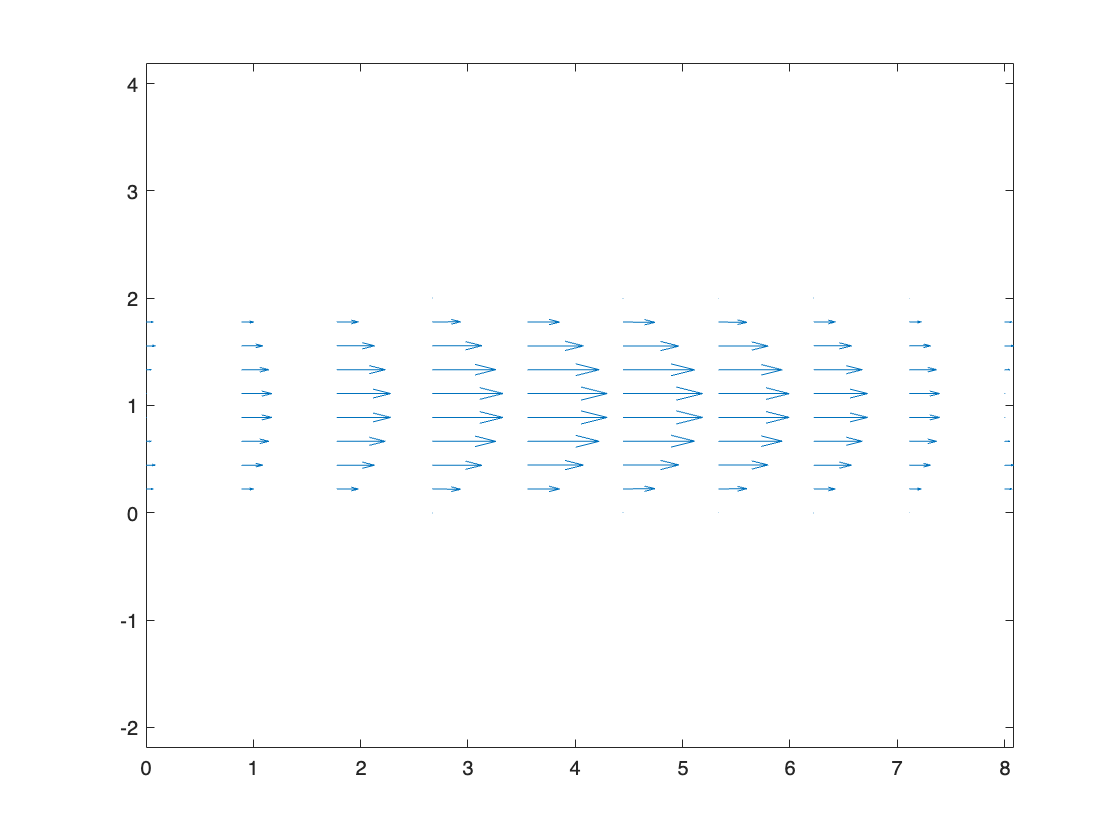

N = 20; % Number of Fourier Coefficients to Compute

Da = 0.4;
mu = 1;
G = 5;
alpha = 3*mu*Da/H^3;
gamma = -G*sech(alpha*L/2)/alpha;
L = 4; % length of permeable portion of the channel
H = 1; % radius of the channel
c = 2*H; % extension length of the channel
xpts =linspace(0,L+2*c,10);
%xpts = [0,c+0.5,L+c+0.5,L+2*c];
%ypts = 1
ypts = linspace(0,2*H,10);
[X,Y] = meshgrid(xpts,ypts);

x = X(:)';
y = Y(:)';
Nvec = (1:N)';
l1 = (2*Nvec-1)*pi/(2*H); % for u_h
l2 = (2*Nvec-1)*pi/(L+2*c); % for u_p
l3 = Nvec*pi/(L+2*c); % for v

% For u_h coefficients
F1 = (exp(-l1.*x)-exp(-2*l1.*(L+2*c)+l1.*x))./(1 - exp(-2*l1.*(L+2*c)));
F2 = exp(l1.*(x-L-2*c)).*(1-exp(-2*l1.*x))./(1-exp(-2*l1.*(L+c)));
Fn = F1+F2;

% For u_p coefficients
%g = @(y,l2,H) (csch(2*H*l2) - coth(2*H*l2)).*sinh(l2.*y) + cosh(l2.*y) - 1;
g = @(y,l2,H) ((2*exp(-2*H*l2) - 1 - exp(-4*H*l2))./(1-exp(-4*H*l2))).*sinh(l2.*y) + cosh(l2.*y) - 1;
Gn = (4*gamma*alpha.*cosh(alpha*((L+2*c)/2)))./((L+2*c)*l2.^3.*(alpha^2+ l2.^2));

% Calculate usoln
U_h = 2*G/H.*sin(l1.*y).*Fn;
U_p = Gn.*(1./l2.^2).*sin(l2.*x).*g(y,l2,H)/mu;
U = U_h + U_p;
uSoln = sum(U); % sum the fourier series terms

% For v coefficients
J = 2*gamma*Da./((L+2*c)^2.*(alpha^2 + l3.^2));
Jn = J.*(Nvec*pi.*sinh(alpha*L/2).*(cos(l3*c)+cos(l3*(L+c))) + alpha*(L+2*c)*cosh(alpha*L/2).*(sin(l3*c)-sin(l3*(L+C))))./sinh(l3*2*H);

V = sin(l3.*x).*Jn.*(sinh(l3.*(2*H-y))- sinh(l3.*y));
vSoln = sum(V);

uGrid = reshape(uSoln,size(X,1),size(X,2));
vGrid = reshape(vSoln,size(X,1),size(X,2));

figure
quiver(X,Y,uGrid,vGrid)
axis equal

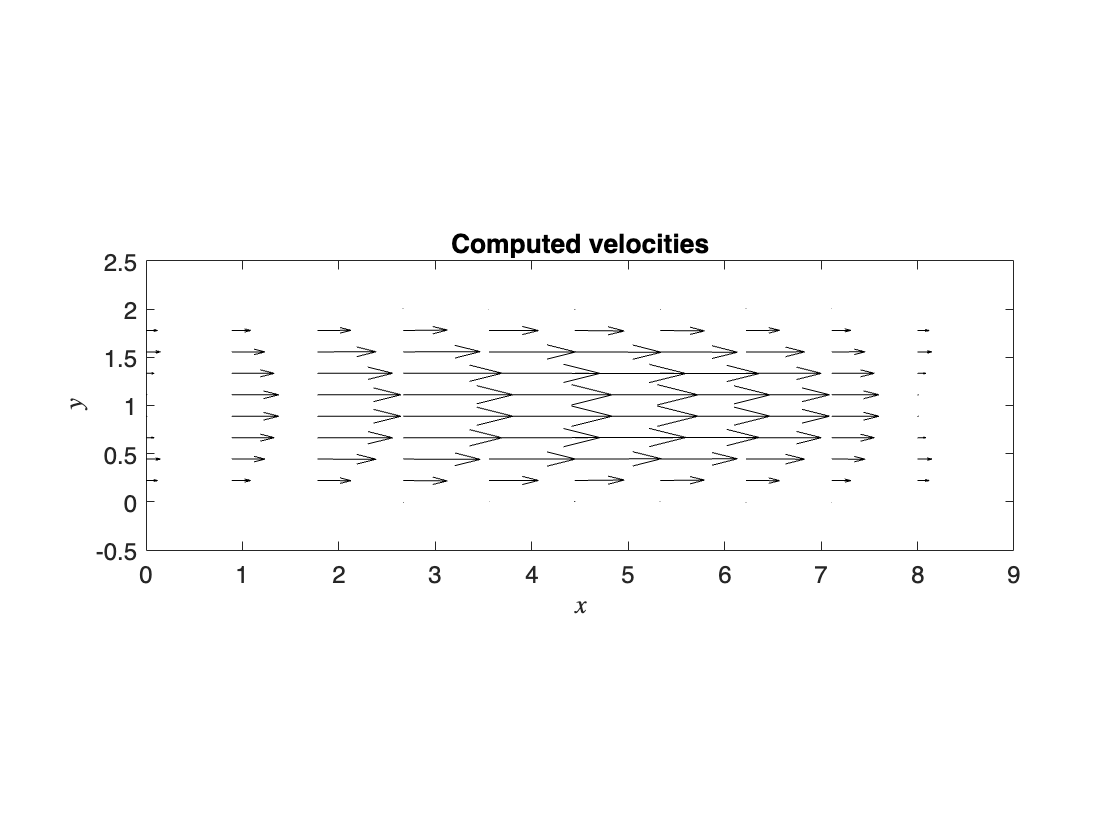

scalefactor = 0.01;
quiver(X,Y,uGrid*scalefactor,vGrid*scalefactor,'k','AutoScale','off')

title('Computed velocities')
%legend('','Exact velocity', 'Computed velocity')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal
axis([x1m(1),x1m(end)+1,x2m(1)-0.5,x2m(end)+0.5])
set(gca,'FontSize',12)